clear all;
close all;
clc;

nBits = 1000000;
M = 4;
symSize = log2(M);
nSymbols = nBits/symSize;

rng default;

SNRdB = 1:10;
nSNR = length(SNRdB);
SNR = 10.^(SNRdB/10);
noiseAmp = 1./SNR;
sigma = sqrt(noiseAmp/2);

symbolSpace = [(1+1i) (1-1i) (-1+1i) (-1-1i)];
symBinRepresentation = ['00'; '01'; '10'; '11'];

a = sqrt(2*SNR*(1-sqrt(1/2)));
b = sqrt(2*SNR*(1+sqrt(1/2)));
ThBER = marcumq(a,b) - 0.5*besseli(a.*b, 1).*exp(-0.5*(a.^2 + b.^2));
SimBER = zeros(nSNR, 1);

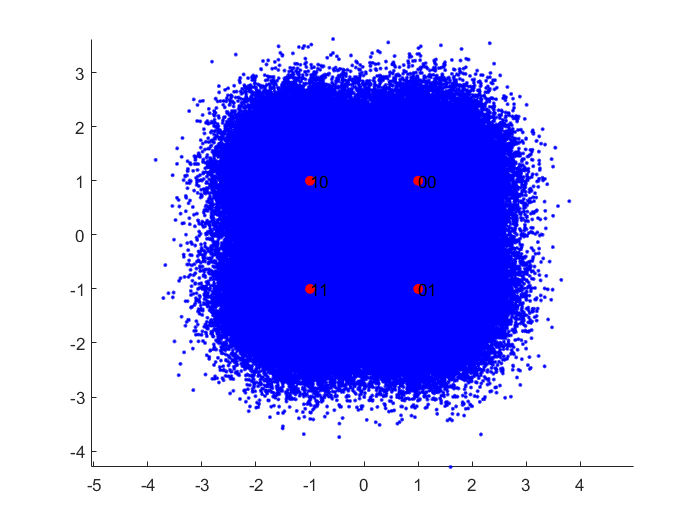

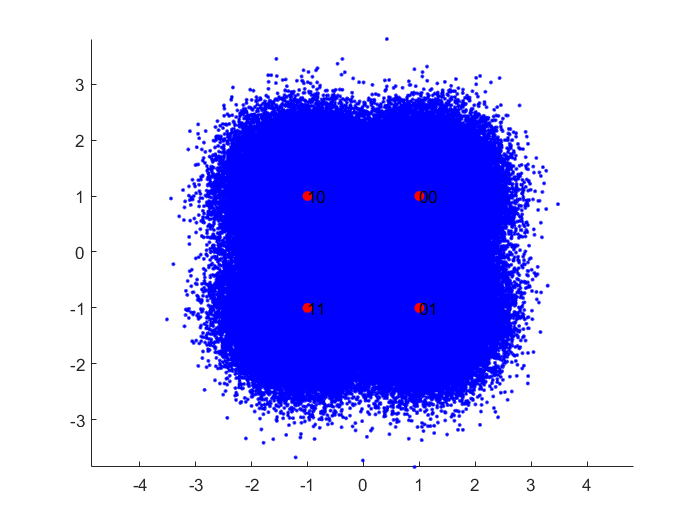

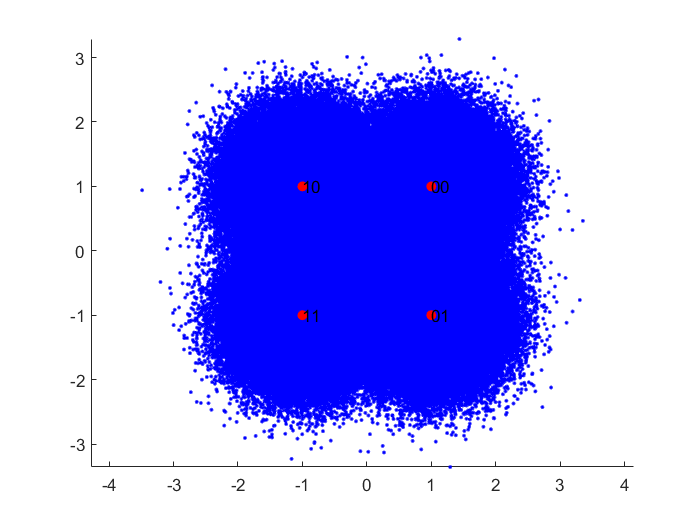

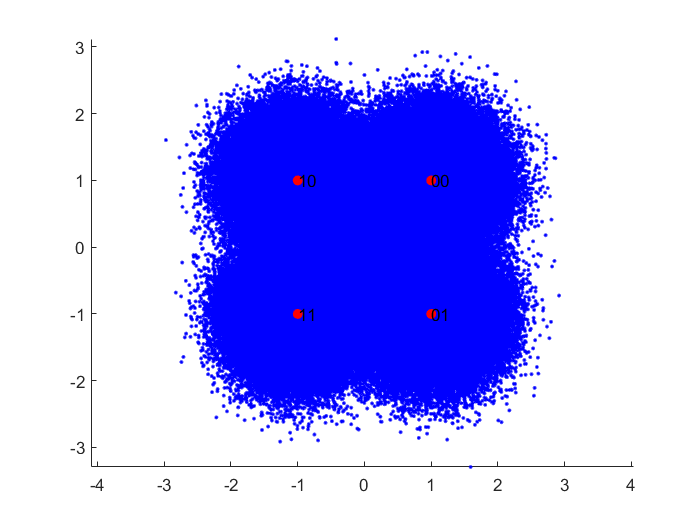

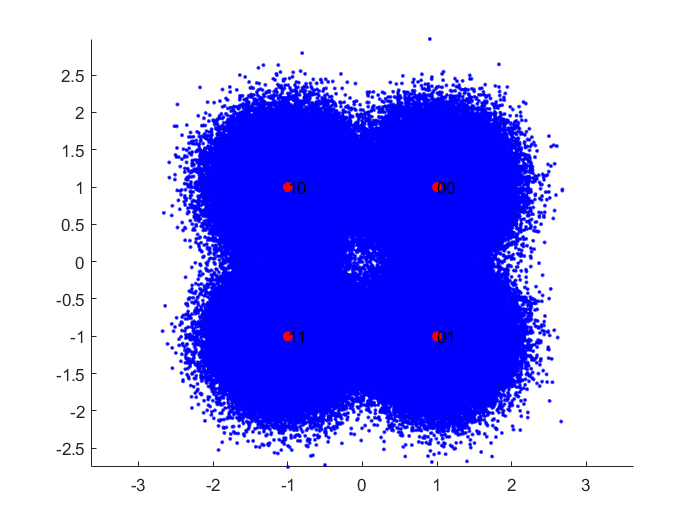

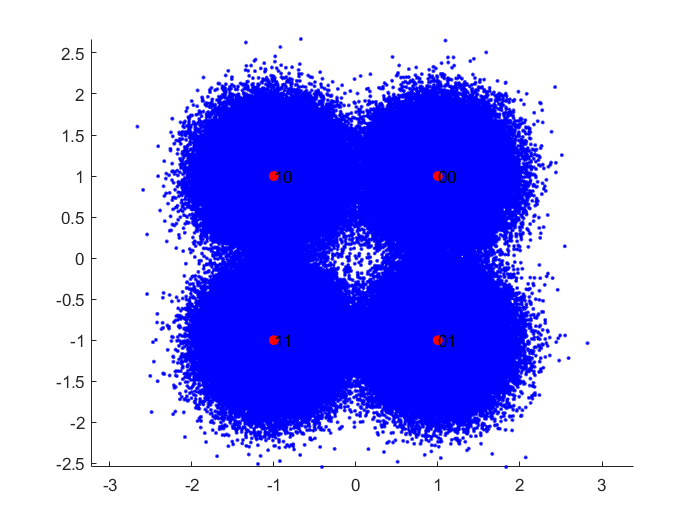

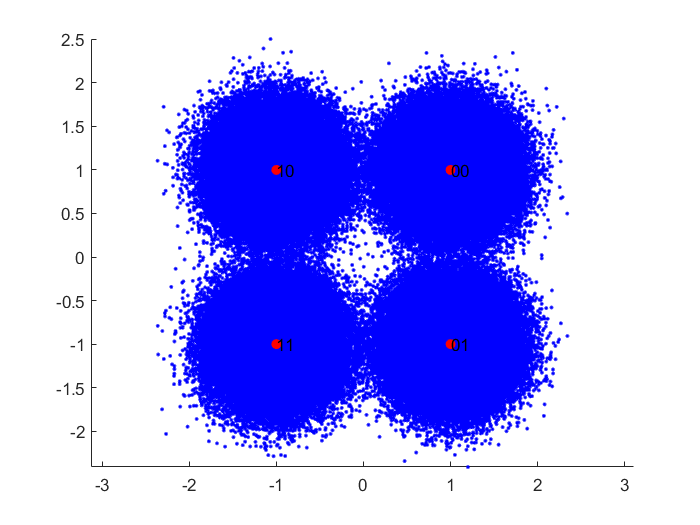

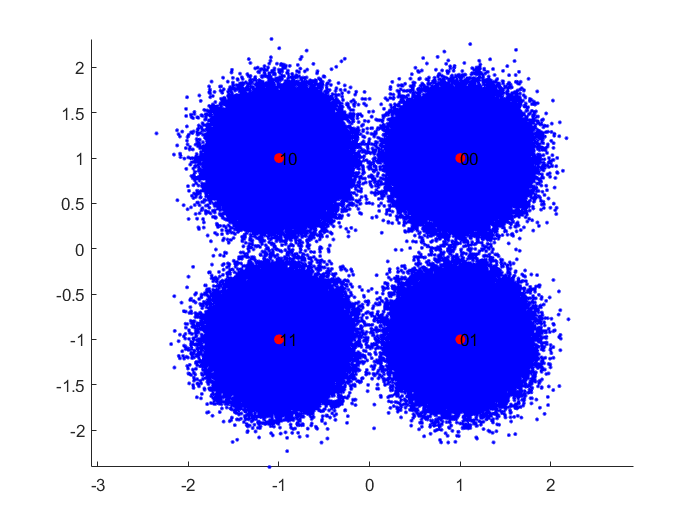

for SNRindex = 1:nSNR
    
    inBinSig = randi([0 1], nBits, 1);

    modSig = DQPSKmodulator(inBinSig);
    
    channelSig = modSig + sigma(SNRindex)*(randn(nSymbols + 1, 1) + 1i*randn(nSymbols + 1, 1));
    
    figure(SNRindex);
    scatter(real(channelSig), imag(channelSig), 'b.');
    hold on;
    scatter(real(symbolSpace), imag(symbolSpace), 'red', 'filled');
    for symIndex = 1:M
        text(real(symbolSpace(symIndex)), imag(symbolSpace(symIndex)), symBinRepresentation(symIndex, :));
    end
    hold off;
    xlabel('In-Phase Component');
    ylabel('Quadrature Component');
    plotTitle = strcat('Constellation with original and erroneous symbols for SNR value =', num2str(SNRdB(SNRindex)), ' dB');
    title(plotTitle);
    axis equal;
  
    outBinSig = DQPSKdemodulator(channelSig, symbolSpace);
    
    SimBER(SNRindex) = sum(inBinSig ~= outBinSig)/nBits;
    
end

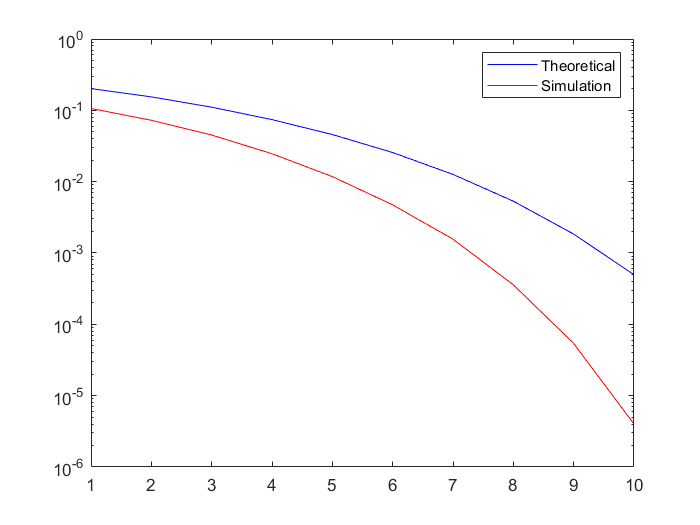

figure(SNRindex+1);
semilogy(SNRdB, ThBER, 'blue');
hold on;
semilogy(SNRdB, SimBER, 'red');
hold off;
grid on;
xlabel('SNR Value (dB) (Eb/No)');
ylabel('Bit Error Rate (BER)');
legend('Theoretical', 'Simulation');

function modSig = DQPSKmodulator(inBinSig)

    nSymbols = length(inBinSig)/2;

    inSymSigI = inBinSig(1:2:end);
    inSymSigQ = inBinSig(2:2:end);
    
    diffEnSigI = zeros(nSymbols + 1, 1);
    diffEnSigI(1) = randi([0 1], 1, 1);
    
    diffEnSigQ = zeros(nSymbols + 1, 1);
    diffEnSigQ(1) = randi([0 1], 1, 1);
    
    for index = 1:nSymbols
        diffEnSigI(index + 1) = not(xor(diffEnSigI(index), inSymSigI(index)));
        diffEnSigQ(index + 1) = not(xor(diffEnSigQ(index), inSymSigQ(index)));
    end
    
    modSigI = 2*diffEnSigI - 1;
    modSigQ = 2*diffEnSigQ - 1;
    
    modSig = -(modSigI + 1i*modSigQ);
end

function outBinSig = DQPSKdemodulator(channelSig, symbolSpace)

    M = 4;
    nSymbols = length(channelSig) - 1;
    nBits = 2 * nSymbols;

    demodSigI = zeros(nSymbols + 1, 1);
    demodSigQ = zeros(nSymbols + 1, 1);
    
    for index = 1:nSymbols + 1
        distVector = zeros(M, 1);
        for symIndex = 1:M
            distVector(symIndex) = norm(symbolSpace(symIndex) - channelSig(index));
        end
        [~, minIndex] = min(distVector);
        demodSigI(index) = -real(symbolSpace(minIndex));
        demodSigQ(index) = -imag(symbolSpace(minIndex));
    end
    
    diffDecSigI = 0.5*(demodSigI + 1);
    diffDecSigQ = 0.5*(demodSigQ + 1);
    
    outBinSig = zeros(nBits, 1);
    
    for index = 1:nSymbols
        outBinSig(2*index - 1) = not(xor(diffDecSigI(index), diffDecSigI(index + 1)));
        outBinSig(2*index) = not(xor(diffDecSigQ(index), diffDecSigQ(index + 1)));
    end

end